v = VideoReader("RoadTraffic.mp4");

frameSum = enhanceImage(im2double(read(v,1)));
for idx = 2:v.NumFrames
    frameSum = frameSum + enhanceImage(im2double(read(v,idx)));
end
avgFrame = frameSum/v.NumFrames;

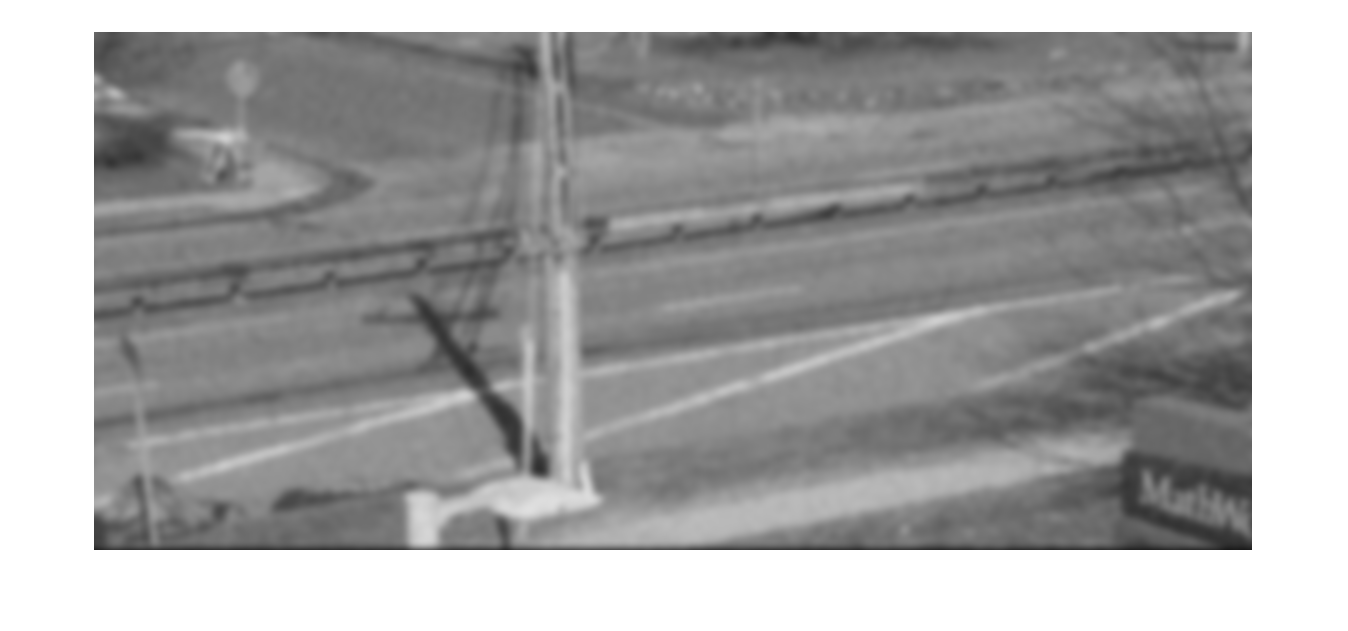

imshow(avgFrame)

montage({background})

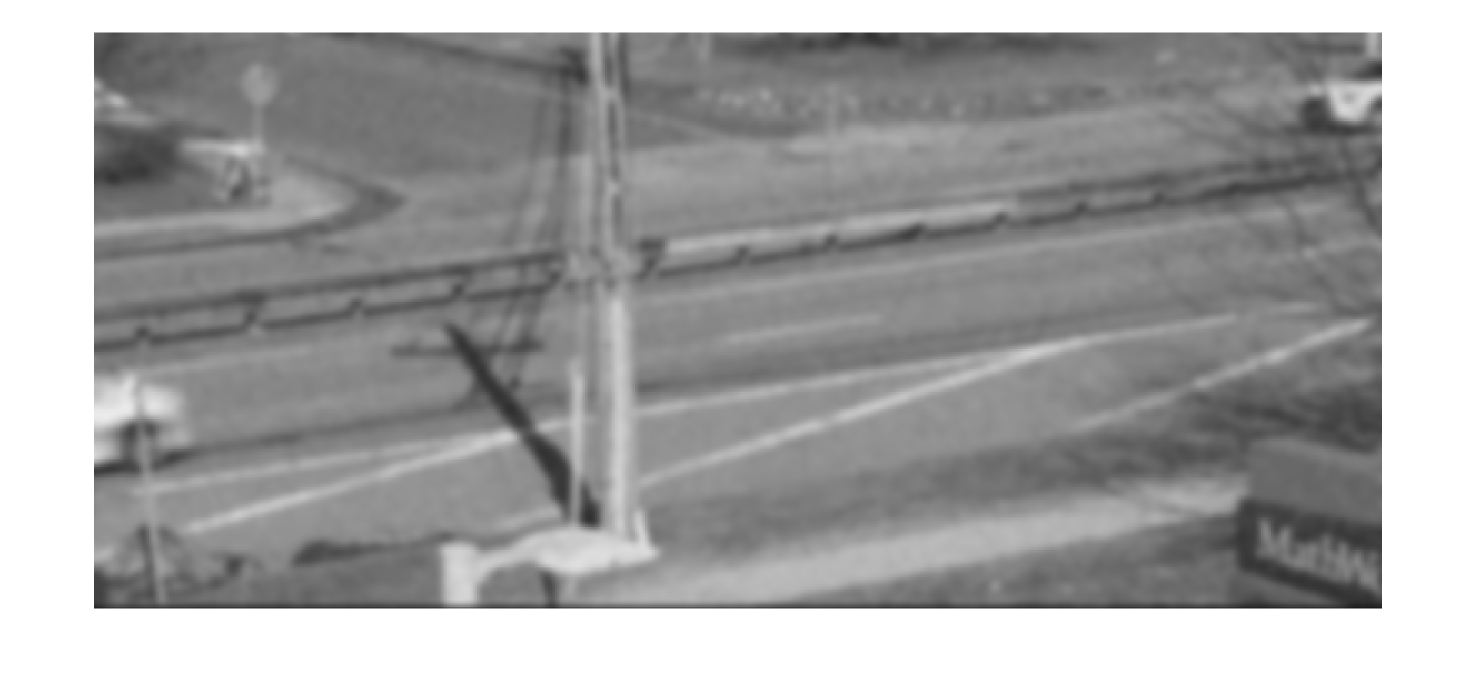

frame = read(v,6);
imgF = enhanceImage(frame);
montage({imgF})

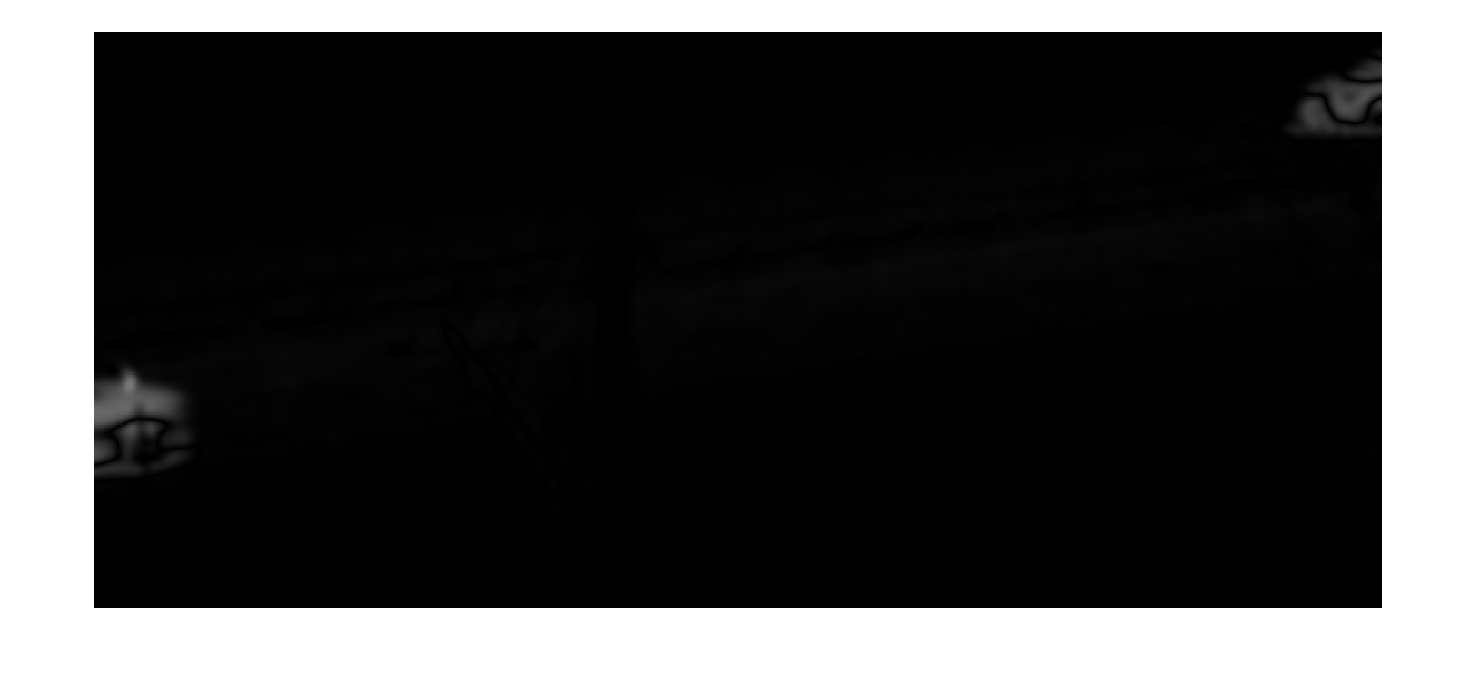

frame = im2double(imgF);
background = avgFrame;
frameDiff = abs(frame-background);
montage({frameDiff})

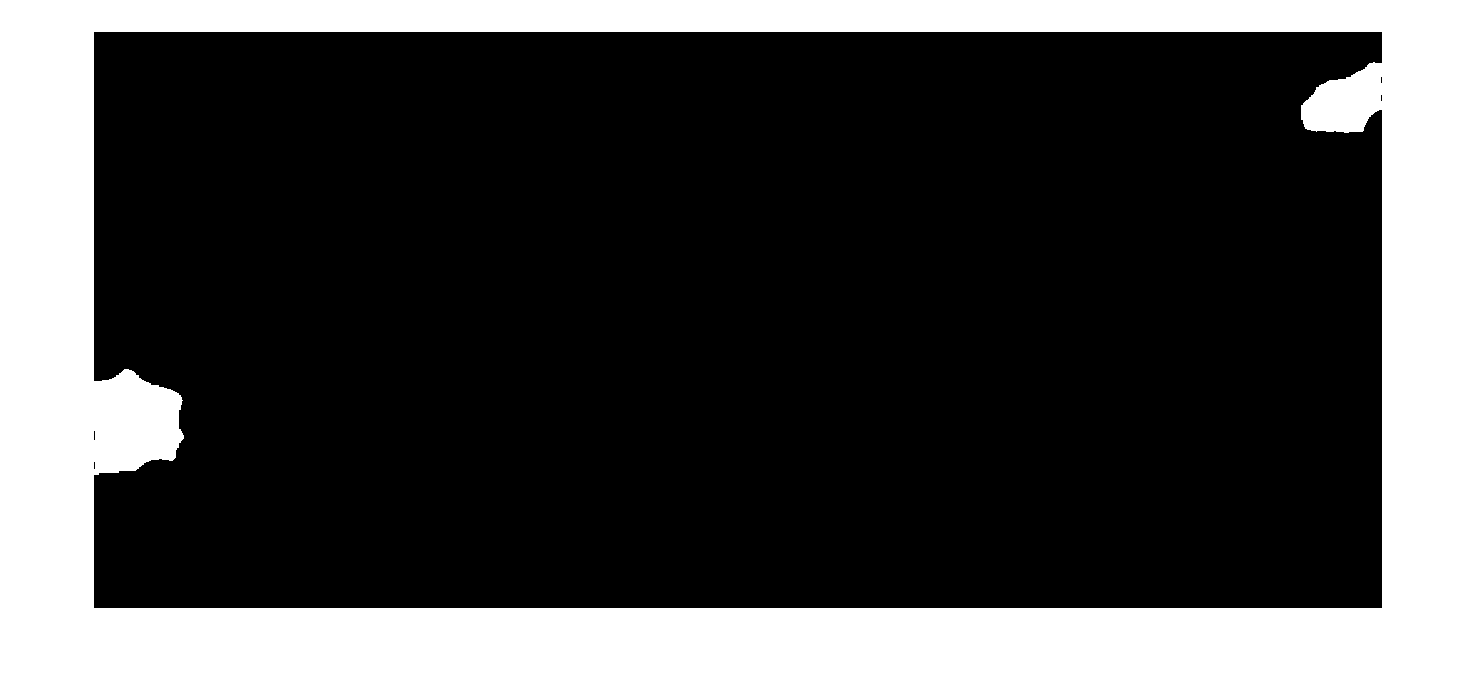

[BW,maskedImage] = segmentImage(frameDiff);
props = regionprops("table",BW, "Area", "BoundingBox");
numRegions = height(props);
meanRegionSize = mean([props.Area]);
totalRegionSize = sum([props.Area]);
regionPropsTable1 = table(numRegions, meanRegionSize, totalRegionSize);
montage({BW})

v1 = VideoWriter("MathWorksTraffic2.mp4", "MPEG-4");

imageSegmenter

background = avgFrame;
BWImg = enhanceImage(frame);
frameDiff = abs(BWImg - background);
[BW,masked] = segmentImage(frameDiff);
montage({BW})

open(v1)    
nFrames = v.NumFrames;
% Initialize empty arrays to store region properties
numRegions = zeros(nFrames, 1);
meanRegionSize = zeros(nFrames, 1);
totalRegionSize = zeros(nFrames, 1);
for idx = 1:v.NumFrames
    frame = im2double(read(v, idx));
    background = avgFrame;
    BWImg = enhanceImage(frame);
    frameDiff = abs(BWImg - background);
    [BW,masked] = segmentImage(frameDiff);
    props = regionprops("table",BW, "Area", "BoundingBox");
    numRegions(idx) = numel(props);
    meanRegionSize(idx) = mean([props.Area]);
    totalRegionSize(idx) = sum([props.Area]);
    vehicleBox = insertShape(frame,"Rectangle", props.BoundingBox,"LineWidth",1,"Color","red");
    % Create a table with the specified properties
    regionPropsTable = table(numRegions, meanRegionSize, totalRegionSize);
    % Write the frame with the bounding boxes to the output video
    writeVideo(v1, vehicleBox);
end
close(v1)


% Display the first few rows of the table
disp(regionPropsTable(1:5, :));

img = im2gray(imread("Rt9Frame1.png"));
BW = enhanceImage(img);
montage({BW})

function enhancedImg = enhanceImage(colorFrame)
    % Convert the image to grayscale
    img = rgb2gray(colorFrame);

    % Remove noise using a Gaussian filter
    imgF = imgaussfilt(img, 4);

    % Output the final result
    enhancedImg = imgF;
end

function [BW,maskedImage] = segmentImage(X)
%segmentImage Segment image using auto-generated code from imageSegmenter app
%  [BW,MASKEDIMAGE] = segmentImage(X) segments image X using auto-generated
%  code from the imageSegmenter app. The final segmentation is returned in
%  BW, and a masked image is returned in MASKEDIMAGE.

% Auto-generated by imageSegmenter app on 21-Nov-2023
%----------------------------------------------------


% Threshold image - manual threshold
BW = X > 1.372500e-01;

% Open mask with disk
radius = 1;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imopen(BW, se);

% Close mask with disk
radius = 25;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imclose(BW, se);

% Create masked image.
maskedImage = X;
maskedImage(~BW) = 0;
end



